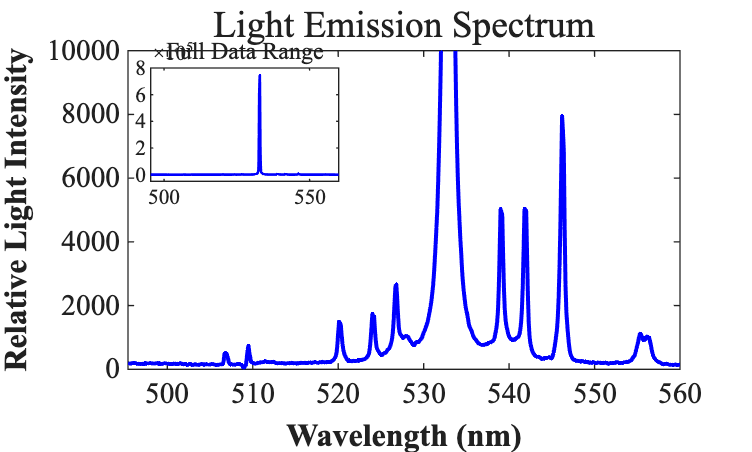

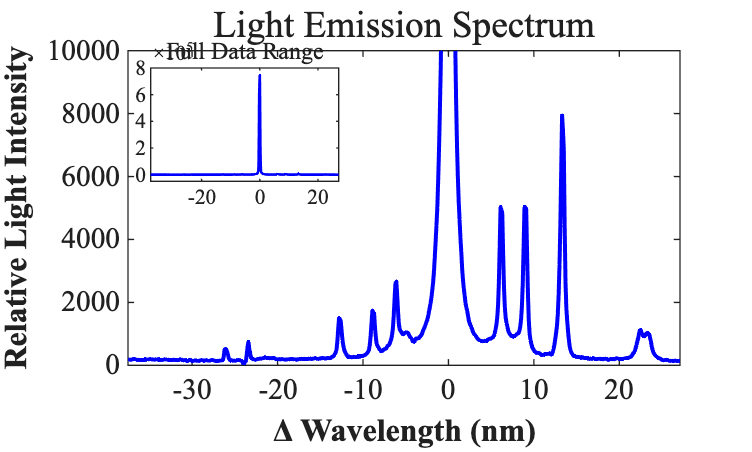

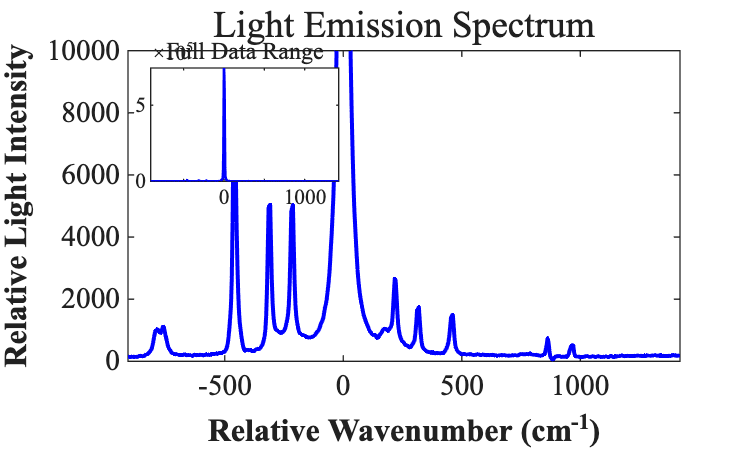

% Read the data from the text file

data = readmatrix('data1.txt');

% Extract the first and second columns
wavelength = data(:, 1);
intensity = data(:, 2);

% Create the figure
figure;

% --- Main Plot ---
% Plot the data on the main axes
plot(wavelength, intensity, 'b-', 'LineWidth', 1.5);

% Apply "Times New Roman" font to the main axes ticks and numbers
set(gca, 'FontName', 'Times New Roman', 'FontSize', 11);

% Add labels and title to the main plot with Times New Roman font
xlabel('Wavelength (nm)', 'FontName', 'Times New Roman', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Relative Light Intensity', 'FontName', 'Times New Roman', 'FontSize', 12, 'FontWeight', 'bold');
title('Light Emission Spectrum', 'FontName', 'Times New Roman', 'FontSize', 14);

% Improve visuals and set axis limits for the main plot
grid off;
xlim([min(wavelength) max(wavelength)]);
ylim([0, 10000]); % Restrict y-axis between 0 and 10000

% --- Inset Plot (Minor Figure) ---
% Define the position for the TOP LEFT [left, bottom, width, height]
% We reduced the 'left' coordinate to 0.20 so it sits on the left side
axes('Position', [0.20, 0.60, 0.25, 0.25]);

% Plot the full data in the inset
plot(wavelength, intensity, 'b-', 'LineWidth', 1);

% Apply "Times New Roman" to the inset axes
set(gca, 'FontName', 'Times New Roman', 'FontSize', 8);

% Add a small title and adjust visuals for the inset
title('Full Data Range', 'FontName', 'Times New Roman', 'FontSize', 9);
xlim([min(wavelength) max(wavelength)]);ylim([-50000, 800000]);
% No ylim restriction here so the full peak is visible
grid off;

% Read the data from the text file
data = readmatrix('data1.txt');

% Extract the first and second columns
original_wavelength = data(:, 1);
intensity = data(:, 2);

% --- Calibration Step ---
% Find the highest peak intensity and its corresponding wavelength index
[~, max_idx] = max(intensity);
peak_wavelength = original_wavelength(max_idx);

% Shift the wavelength so the highest peak is at exactly 0
shifted_wavelength = original_wavelength - peak_wavelength;

% Create the figure
figure;

% --- Main Plot ---
% Plot the data on the main axes using the shifted wavelength
plot(shifted_wavelength, intensity, 'b-', 'LineWidth', 1.5);

% Apply "Times New Roman" font to the main axes ticks and numbers
set(gca, 'FontName', 'Times New Roman', 'FontSize', 11);

% Add labels and title to the main plot with Times New Roman font
xlabel('\Delta Wavelength (nm)', 'FontName', 'Times New Roman', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Relative Light Intensity', 'FontName', 'Times New Roman', 'FontSize', 12, 'FontWeight', 'bold');
title('Light Emission Spectrum', 'FontName', 'Times New Roman', 'FontSize', 14);

% Improve visuals and set axis limits for the main plot
grid off;
xlim([min(shifted_wavelength) max(shifted_wavelength)]);
ylim([0, 10000]); % Restrict y-axis between 0 and 10000

% --- Inset Plot (Minor Figure) ---
% Define the position for the TOP LEFT [left, bottom, width, height]
axes('Position', [0.20, 0.60, 0.25, 0.25]);

% Plot the full data in the inset using the shifted wavelength
plot(shifted_wavelength, intensity, 'b-', 'LineWidth', 1);

% Apply "Times New Roman" to the inset axes
set(gca, 'FontName', 'Times New Roman', 'FontSize', 8);

% Add a small title and adjust visuals for the inset
title('Full Data Range', 'FontName', 'Times New Roman', 'FontSize', 9);
xlim([min(shifted_wavelength) max(shifted_wavelength)]);ylim([-50000, 800000]);
% No ylim restriction here so the full highest peak is visible
grid off;

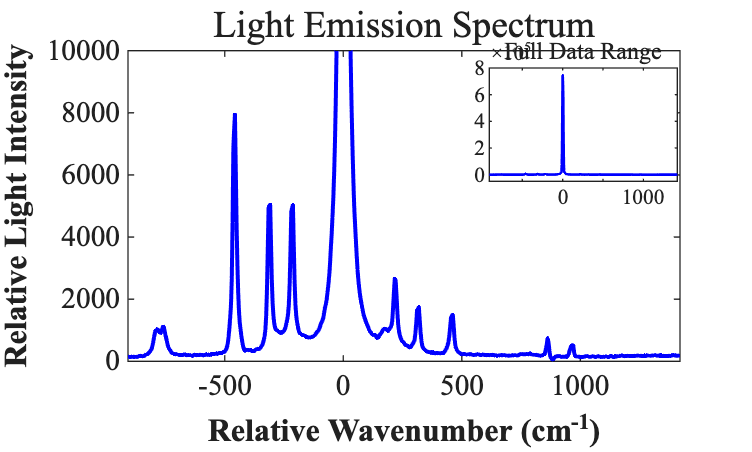

% Read the data from the text file
data = readmatrix('data1.txt');

% Extract the first and second columns
original_wavelength = data(:, 1);
intensity = data(:, 2);

% --- Calibration Step ---
% Find the highest peak intensity and its corresponding wavelength index
[~, max_idx] = max(intensity);
peak_wavelength = original_wavelength(max_idx);

% Calculate relative wavenumber (cm^-1) as Data minus Peak
% Formula: (1 / original_wavelength - 1 / peak_wavelength) * 10^7
relative_wavenumber = (1 ./ original_wavelength - 1 / peak_wavelength) * 1e7;

% Create the figure
figure;

% --- Main Plot ---
% Plot the data on the main axes using relative wavenumber
plot(relative_wavenumber, intensity, 'b-', 'LineWidth', 1.5);

% Apply "Times New Roman" font to the main axes ticks and numbers
set(gca, 'FontName', 'Times New Roman', 'FontSize', 11);

% Add labels and title to the main plot with Times New Roman font
xlabel('Relative Wavenumber (cm^{-1})', 'FontName', 'Times New Roman', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Relative Light Intensity', 'FontName', 'Times New Roman', 'FontSize', 12, 'FontWeight', 'bold');
title('Light Emission Spectrum', 'FontName', 'Times New Roman', 'FontSize', 14);

% Improve visuals and set axis limits for the main plot
grid off;
xlim([min(relative_wavenumber) max(relative_wavenumber)]);
ylim([0, 10000]); % Restrict y-axis between 0 and 10000

% --- Inset Plot (Minor Figure) ---
% Define the position for the TOP RIGHT [left, bottom, width, height]
% Changed the first value from 0.20 (left) to 0.65 (right)
axes('Position', [0.65, 0.60, 0.25, 0.25]);

% Plot the full data in the inset using relative wavenumber
plot(relative_wavenumber, intensity, 'b-', 'LineWidth', 1);

% Apply "Times New Roman" to the inset axes
set(gca, 'FontName', 'Times New Roman', 'FontSize', 8);

% Add a small title and adjust visuals for the inset
title('Full Data Range', 'FontName', 'Times New Roman', 'FontSize', 9);
xlim([min(relative_wavenumber) max(relative_wavenumber)]);ylim([-50000, 800000]);
% No ylim restriction here so the full highest peak is visible
grid off;

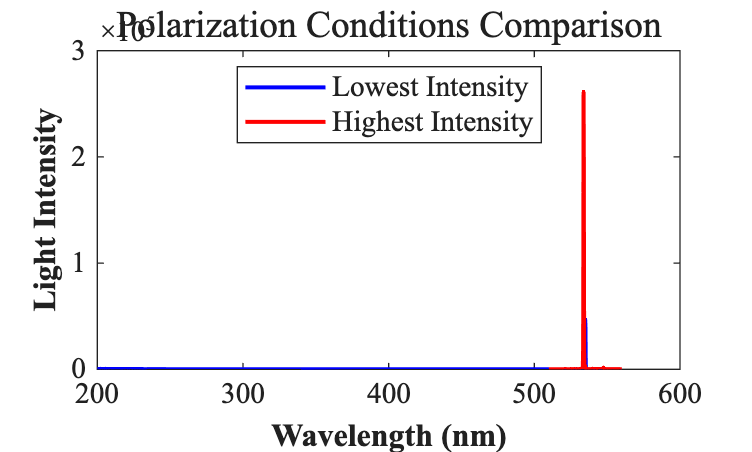

% Read the data from the text files
% Assuming the files are named 'lowest.txt' and 'highest_peak.txt'
data_lowest = readmatrix('lowest.txt');
data_highest = readmatrix('highest.txt');

% Extract wavelength and intensity columns for lowest
wave_low = data_lowest(:, 1);
int_low = data_lowest(:, 2);

% Extract wavelength and intensity columns for highest peaks
wave_high = data_highest(:, 1);
int_high = data_highest(:, 2);

% Create the figure
figure;

% --- Plotting ---
% Plot the lowest intensity data as a continuous blue line
plot(wave_low, int_low, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Lowest Intensity');

% Hold the axis to plot the second dataset on top
hold on;

% Plot the highest intensity data as a red line with circle markers
plot(wave_high, int_high, 'r-', 'LineWidth', 1.5, 'MarkerSize', 6, 'MarkerFaceColor', 'r', 'DisplayName', 'Highest Intensity');

% Apply "Times New Roman" font to the axes
set(gca, 'FontName', 'Times New Roman', 'FontSize', 11);

% Add labels, title, and legend with Times New Roman font
xlabel('Wavelength (nm)', 'FontName', 'Times New Roman', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Light Intensity', 'FontName', 'Times New Roman', 'FontSize', 12, 'FontWeight', 'bold');
title('Polarization Conditions Comparison', 'FontName', 'Times New Roman', 'FontSize', 14);

% Add a legend to distinguish the two line types
legend('Location', 'best', 'FontName', 'Times New Roman', 'FontSize', 11);

% Improve visuals
grid off;
hold off;

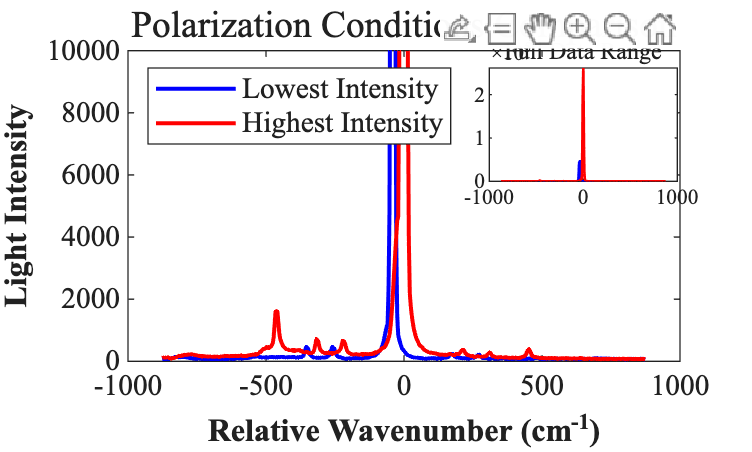

% Read the data from the text files
data_lowest = readmatrix('lowest.txt');
data_highest = readmatrix('highest.txt'); 

% Extract wavelength and intensity columns for lowest
wave_low = data_lowest(:, 1);
int_low = data_lowest(:, 2);

% Extract wavelength and intensity columns for highest peaks
wave_high = data_highest(:, 1);
int_high = data_highest(:, 2);

% --- THE FIX: Use a Single Reference Peak ---
% Find the lambda__highest_peak from the highest intensity dataset
[~, max_idx_high] = max(int_high);
lambda_highest_peak = wave_high(max_idx_high);

% Calculate relative wavenumber for BOTH datasets using the SAME reference peak
% Formula: (1 / lambda - 1 / lambda__highest_peak) * 1e7
rel_wave_low = (1 ./ wave_low - 1 / lambda_highest_peak) * 1e7;
rel_wave_high = (1 ./ wave_high - 1 / lambda_highest_peak) * 1e7;

% Create the figure
figure;

% --- Main Plot ---
% Plot the lowest intensity data
plot(rel_wave_low, int_low, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Lowest Intensity');
hold on;

% Plot the highest intensity data
plot(rel_wave_high, int_high, 'r-', 'LineWidth', 1.5, 'MarkerSize', 6, 'MarkerFaceColor', 'r', 'DisplayName', 'Highest Intensity');

% Apply "Times New Roman" font to the main axes
set(gca, 'FontName', 'Times New Roman', 'FontSize', 11);

% Add labels, title, and legend with Times New Roman font
xlabel('Relative Wavenumber (cm^{-1})', 'FontName', 'Times New Roman', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Light Intensity', 'FontName', 'Times New Roman', 'FontSize', 12, 'FontWeight', 'bold');
title('Polarization Conditions Comparison', 'FontName', 'Times New Roman', 'FontSize', 14);

% Place legend in the top-left (northwest) to avoid overlapping the inset
legend('Location', 'northwest', 'FontName', 'Times New Roman', 'FontSize', 11);

% Adjust main plot visuals
ylim([0, 10000]); % Restrict y-axis between 0 and 10000
grid off; % Turn grid off
hold off;

% --- Inset Plot (Minor Figure) ---
% Define the position for the TOP RIGHT [left, bottom, width, height]
axes('Position', [0.65, 0.60, 0.25, 0.25]);

% Plot both datasets in the inset using relative wavenumber
plot(rel_wave_low, int_low, 'b-', 'LineWidth', 1);
hold on;
plot(rel_wave_high, int_high, 'r-', 'LineWidth', 1, 'MarkerSize', 4, 'MarkerFaceColor', 'r');

% Apply "Times New Roman" to the inset axes
set(gca, 'FontName', 'Times New Roman', 'FontSize', 8);

% Add a small title and adjust visuals for the inset
title('Full Data Range', 'FontName', 'Times New Roman', 'FontSize', 9);
grid off; 
hold off;

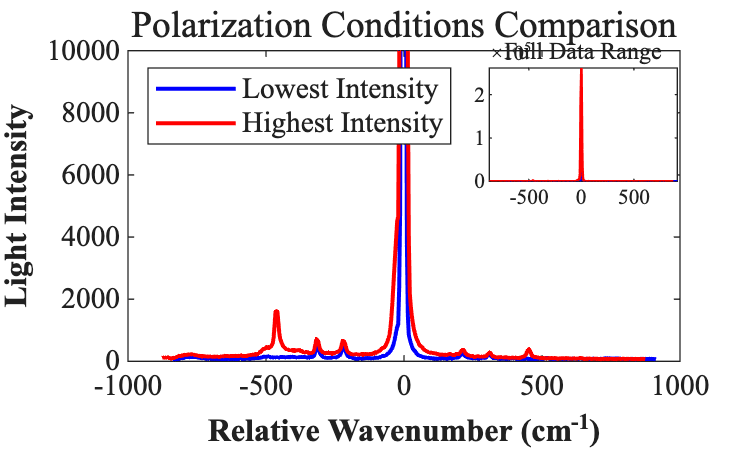

% 读取两组数据
data_lowest = readmatrix('lowest.txt');
data_highest = readmatrix('highest.txt'); 

% 提取波长和强度
wave_low = data_lowest(:, 1);
int_low = data_lowest(:, 2);

wave_high = data_highest(:, 1);
int_high = data_highest(:, 2);

% --- 核心修改：消除仪器误差，各自对齐到 0 ---

% 1. 处理 Lowest Intensity 数据
% 寻找蓝色数据自己的最高峰
[~, max_idx_low] = max(int_low);
lambda_peak_low = wave_low(max_idx_low); % 这个值大概是 534.9 nm
% 计算相对波数：使用蓝色数据自己的最高峰作为基准
rel_wave_low = (1 ./ wave_low - 1 / lambda_peak_low) * 1e7;

% 2. 处理 Highest Intensity 数据
% 寻找红色数据自己的最高峰
[~, max_idx_high] = max(int_high);
lambda_peak_high = wave_high(max_idx_high); % 这个值大概是 533.8 nm
% 计算相对波数：使用红色数据自己的最高峰作为基准
rel_wave_high = (1 ./ wave_high - 1 / lambda_peak_high) * 1e7;


% 创建图形
figure;

% --- 主图 ---
% 绘制 Lowest Intensity (蓝色实线)
plot(rel_wave_low, int_low, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Lowest Intensity');
hold on;
% 绘制 Highest Intensity (红色圆点+实线)
plot(rel_wave_high, int_high, 'r-', 'LineWidth', 1.5, 'MarkerSize', 6, 'MarkerFaceColor', 'r', 'DisplayName', 'Highest Intensity');

% 设置主图字体为 Times New Roman
set(gca, 'FontName', 'Times New Roman', 'FontSize', 11);

% 主图标签，包含 LaTeX 格式的上标
xlabel('Relative Wavenumber (cm^{-1})', 'FontName', 'Times New Roman', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Light Intensity', 'FontName', 'Times New Roman', 'FontSize', 12, 'FontWeight', 'bold');
title('Polarization Conditions Comparison', 'FontName', 'Times New Roman', 'FontSize', 14);

% 图例放在左上角
legend('Location', 'northwest', 'FontName', 'Times New Roman', 'FontSize', 11);

% 限制显示范围
xlim([-1000, 1000]); % 强行截取峰值附近的 X 轴，让0点居中显示
ylim([0, 10000]);    % 限制 Y 轴
grid off; % 关闭网格
hold off;

% --- 右上角小图 (全景图) ---
% 定义小图位置 [left, bottom, width, height]
axes('Position', [0.65, 0.60, 0.25, 0.25]);

% 在小图中绘制两组数据
plot(rel_wave_low, int_low, 'b-', 'LineWidth', 1);
hold on;
plot(rel_wave_high, int_high, 'r-', 'LineWidth', 1, 'MarkerSize', 4, 'MarkerFaceColor', 'r');

% 小图的格式设置
set(gca, 'FontName', 'Times New Roman', 'FontSize', 8);
title('Full Data Range', 'FontName', 'Times New Roman', 'FontSize', 9);

% 小图不限制 Y 轴，但对齐 X 轴的范围以显示完整全景
xlim([min([rel_wave_low; rel_wave_high]), max([rel_wave_low; rel_wave_high])]); 
grid off; 
hold off;

%% =========================================================================
%  Raman Spectroscopy — v13b  (6 main peaks only)
% =========================================================================

clc; clear; close all;

%% --- Load ----------------------------------------------------------------
data_low  = load('lowest.txt');
data_high = load('highest.txt');
lambda_low=data_low(:,1);   I_low=data_low(:,2);
lambda_high=data_high(:,1); I_high=data_high(:,2);

%% --- Wavelength -> Relative Wavenumber -----------------------------------
[~,idx]=max(I_high); lambda_peak=lambda_high(idx);
fprintf('lambda_peak = %.4f nm\n', lambda_peak);

lambda_peak = 533.8000 nm



x_low  = (1./lambda_low  - 1/lambda_peak)*1e7;
x_high = (1./lambda_high - 1/lambda_peak)*1e7;

rl=[-1500 1500];
mk=x_low>=rl(1)&x_low<=rl(2);
[x_low,si]=sort(x_low(mk)); I_low=I_low(mk); I_low=I_low(si);
mk=x_high>=rl(1)&x_high<=rl(2);
[x_high,si]=sort(x_high(mk)); I_high=I_high(mk); I_high=I_high(si);

%% --- Parameters ----------------------------------------------------------
peak_zone   = 60;
blend_width = 40;
mask_width  = 110;

% *** Peak detection: tune these two to get exactly 6 peaks ***
min_peak_height  = 150;   % raise to filter noise/small peaks
min_peak_dist_cm = 65;    % raise to prevent adjacent detections on same peak

%% --- Compute baseline & pure spectrum ------------------------------------
baseline_high = fit_and_correct_v10(x_high, I_high, peak_zone, blend_width);
pure_high     = I_high - baseline_high;

pure_plot = pure_high;
pure_plot(abs(x_high) < mask_width) = NaN;

%% --- Peak detection ------------------------------------------------------
valid = ~isnan(pure_plot) & pure_plot > 0;
x_v   = x_high(valid);
y_v   = pure_high(valid);

dx_mean  = mean(diff(x_high));
min_samp = max(round(min_peak_dist_cm / dx_mean), 1);

[pks, locs] = findpeaks(y_v, ...
    'MinPeakHeight',   min_peak_height, ...
    'MinPeakDistance', min_samp, ...
    'SortStr',         'descend');

pk_x = x_v(locs);
pk_y = pks;

% Print table sorted by wavenumber
fprintf('\n=== Detected Raman Peaks ===\n');


=== Detected Raman Peaks ===


fprintf('  %-10s  %-14s\n', 'x (cm-1)', 'Height (a.u.)');

  x (cm-1)    Height (a.u.) 


fprintf('  %s\n', repmat('-', 1, 26));

  --------------------------


[~,so] = sort(pk_x);
for k = 1:numel(so)
    fprintf('  %+8.1f    %10.1f\n', pk_x(so(k)), pk_y(so(k)));
end

    -462.1        1508.8
    -317.4         582.7
    -221.9         502.6
    +213.0         203.2
    +310.4         152.6
    +452.9         282.3


fprintf('  Total peaks found: %d\n', numel(pk_x));

  Total peaks found: 6


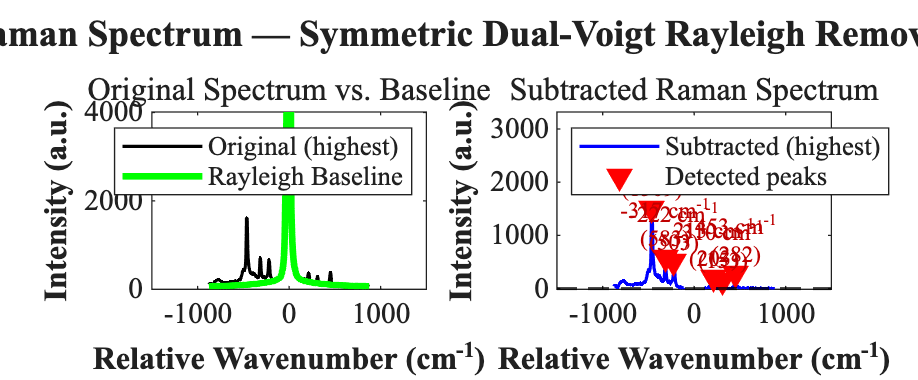


%% --- Plot ----------------------------------------------------------------
fn='Times New Roman'; ls=12; ts=14;
fig=figure('Color','w','Position',[80 80 1400 580]);

subplot(1,2,1); hold on;
plot(x_high, I_high,        'k-','LineWidth',1.2,'DisplayName','Original (highest)');
plot(x_high, baseline_high, 'g-','LineWidth',2.5,'DisplayName','Rayleigh Baseline');
hold off;
xlabel('Relative Wavenumber (cm^{-1})','FontName',fn,'FontSize',ls,'FontWeight','bold');
ylabel('Intensity (a.u.)','FontName',fn,'FontSize',ls,'FontWeight','bold');
title('Original Spectrum vs. Baseline','FontName',fn,'FontSize',ts);
xlim(rl);
side=I_high(abs(x_high)>80);
ylim([0, prctile(side,99.5)*2.5]);
legend('Location','northeast','FontName',fn,'FontSize',10);
set(gca,'FontName',fn,'FontSize',11,'Box','on'); grid off;

subplot(1,2,2); hold on;
plot(x_high, pure_plot,'b-','LineWidth',1.2,'DisplayName','Subtracted (highest)');
yline(0,'k--','LineWidth',1.2,'HandleVisibility','off');

if ~isempty(pk_x)
    plot(pk_x, pk_y, 'rv','MarkerSize',8,'MarkerFaceColor','r',...
         'DisplayName','Detected peaks');
    % Compute a clean vertical offset for labels
    sp_tmp = pure_plot(~isnan(pure_plot));
    y_top  = max(sp_tmp);
    offset = y_top * 0.05;
    for k = 1:numel(pk_x)
        label = sprintf('%d cm^{-1}\n(%d)', round(pk_x(k)), round(pk_y(k)));
        text(pk_x(k), pk_y(k) + offset, label, ...
             'FontName',fn,'FontSize',8.5,...
             'HorizontalAlignment','center','VerticalAlignment','bottom',...
             'Color',[0.75 0 0]);
    end
end
hold off;

xlabel('Relative Wavenumber (cm^{-1})','FontName',fn,'FontSize',ls,'FontWeight','bold');
ylabel('Intensity (a.u.)','FontName',fn,'FontSize',ls,'FontWeight','bold');
title('Subtracted Raman Spectrum','FontName',fn,'FontSize',ts);
xlim(rl);
sp = pure_plot(abs(x_high)>mask_width & abs(x_high)<1200);
sp = sp(~isnan(sp));
if ~isempty(sp) && max(sp)>0
    ylim([max(min(sp)*1.2, -max(sp)*0.1), max(sp)*2.2]);
end
legend('Location','northwest','FontName',fn,'FontSize',10);
set(gca,'FontName',fn,'FontSize',11,'Box','on'); grid off;

sgtitle('Raman Spectrum — Symmetric Dual-Voigt Rayleigh Removal',...
        'FontName',fn,'FontSize',ts,'FontWeight','bold');
saveas(fig,'raman_result_v13b.png');

fprintf('\nSaved: raman_result_v13b.png\n');


Saved: raman_result_v13b.png




%% =========================================================================
function baseline = fit_and_correct_v10(x, y, peak_zone, blend_width)
    model = @(p, xv) p(7) ...
        + p(1).*(p(3)./(1+(abs(xv)./p(2)).^2) + (1-p(3)).*exp(-log(2).*(abs(xv)./p(2)).^2)) ...
        + p(4).*(p(6)./(1+(abs(xv)./p(5)).^2) + (1-p(6)).*exp(-log(2).*(abs(xv)./p(5)).^2));

    rmask = x >= 0;
    xr = x(rmask);  yr = y(rmask);  nr = numel(xr);

    off0  = max(prctile(yr(xr>600), 10), 0);
    y_mid = median(yr(xr>120 & xr<400));
    y_top = max(yr(xr<8));
    Ab0   = max(y_mid - off0, 1);
    An0   = max(y_top - y_mid, 1);

    p0 = [An0, 15, 0.9, Ab0, 200, 0.5, off0];
    lb = [0,   2,  0,   0,   30,  0,   0   ];
    ub = [y_top*2, 150, 1, y_top, 1500, 1, off0*5+1];

    opts = optimoptions('lsqcurvefit','Display','off',...
           'MaxIterations',8000,'FunctionTolerance',1e-14,'StepTolerance',1e-14);

    w = ones(nr,1); p_fit = p0;
    for iter = 1:25
        sw = sqrt(w);
        try
            p_fit = lsqcurvefit(@(p,xv) model(p,xv).*sw, p_fit, xr, yr.*sw, lb, ub, opts);
        catch, break; end
        res = yr - model(p_fit, xr);
        neg = res(res<0);
        sig = max(std(neg)*1.5, 1e-3);
        w = ones(nr,1);
        pos = res>0;
        w(pos) = sig.^2./(sig.^2+res(pos).^2);
        w = max(w, 1e-4);
    end

    baseline = model(p_fit, x);
    baseline = max(baseline, 0);

    dx_mean  = mean(diff(x));
    smth_pts = max(round(3/dx_mean), 3);
    y_smooth = movmean(y, smth_pts);
    raw_lift = max(y_smooth - baseline, 0);

    ax    = abs(x);
    alpha = zeros(size(x));
    inner = ax <= peak_zone;
    trans = ax > peak_zone & ax <= peak_zone + blend_width;
    alpha(inner) = 1;
    alpha(trans) = cos(pi/2 * (ax(trans) - peak_zone) / blend_width).^2;

    baseline = baseline + alpha .* raw_lift;
    baseline = max(baseline, 0);
    baseline = baseline(:);
end


函数 'fit_and_correct_v10' 已在此作用域内声明。